# **利用PDE求解静态场问题**

**考虑一个静态场问题，其对应的定解问题如下：**

       
$$\begin{array}{l}
\Delta u=0\\
{u\left|\right.}_{x=0} =0,{u\left|\right.}_{x=1} =0\\
{u\left|\right.}_{y=0} =0,{u\left|\right.}_{y=1} =\sin \left(2\pi x\right)
\end{array}$$


**        已知正方形边界四边上的电势分布值，然后计算正方形内部的电势分布。**

**        用分离变量法得到的解析解为：**


$$u=\frac{1}{\sinh \left(2\pi \right)}\sin \left(2\pi x\right)\sinh \left(2\pi y\right)$$


**        绘制得到的该函数的图像为：**

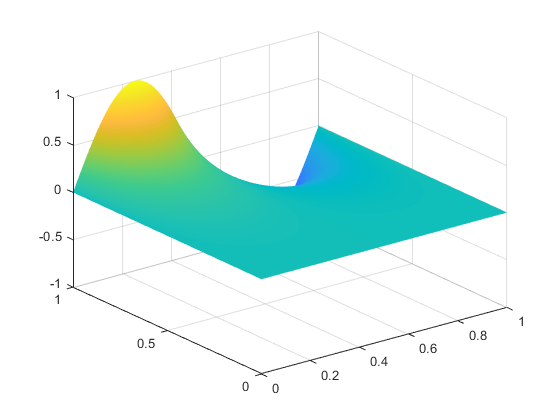

x=linspace(0,1,100);                     	%x取从0到1区间的100个点
y=linspace(0,1,100);                     	%y取从0到1区间的100个点
[X,Y]=meshgrid(x,y);                    	%绘制网格，并将格点坐标赋于X和Y
u=1/(sinh(2*pi))*sin(2*pi*X).*sinh(2*pi*Y); %计算电势值
surf(X,Y,u);                             	%绘制曲面图 
shading interp;                           	%曲面色彩做插值，使色彩平滑过渡

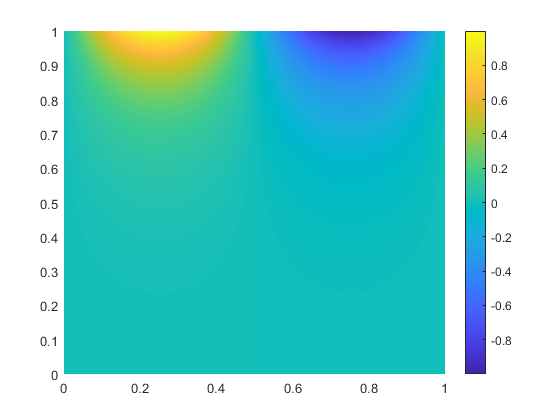

figure;                                 	%创建新的图形窗口
pcolor(X,Y,u);                           	%绘制伪彩色图
shading interp;                           	%色彩做插值处理
colorbar;                               	%绘制带色阶的颜色条
set(gcf,'Visible','on');   	    %强制图片弹出显示

**利用PDETool进行数值求解，并与解析法得到的结果进行对照:**

        **①在matlab的命令行，输入PDETool，进入图形界面**

        **②在工具栏单击矩形绘制按钮，绘制一个边长为1的正方形，R1**

        **③在工具栏单击边界条件设定按钮，根据题目设置狄氏边界条件**

        **④单击方程类型设置按钮，选择椭圆类型，并设置f为0，表示齐次方程**

        **⑤单击网格生成按钮，产生有限元网络**

        **⑥单击细化网格按钮二次，对产生的网格进行细化**

        **⑦单击求解按钮，给出所得解的伪彩色示意图**

        **⑧单击绘图按钮，选择Height，可以得到解的高度图，即曲面图**

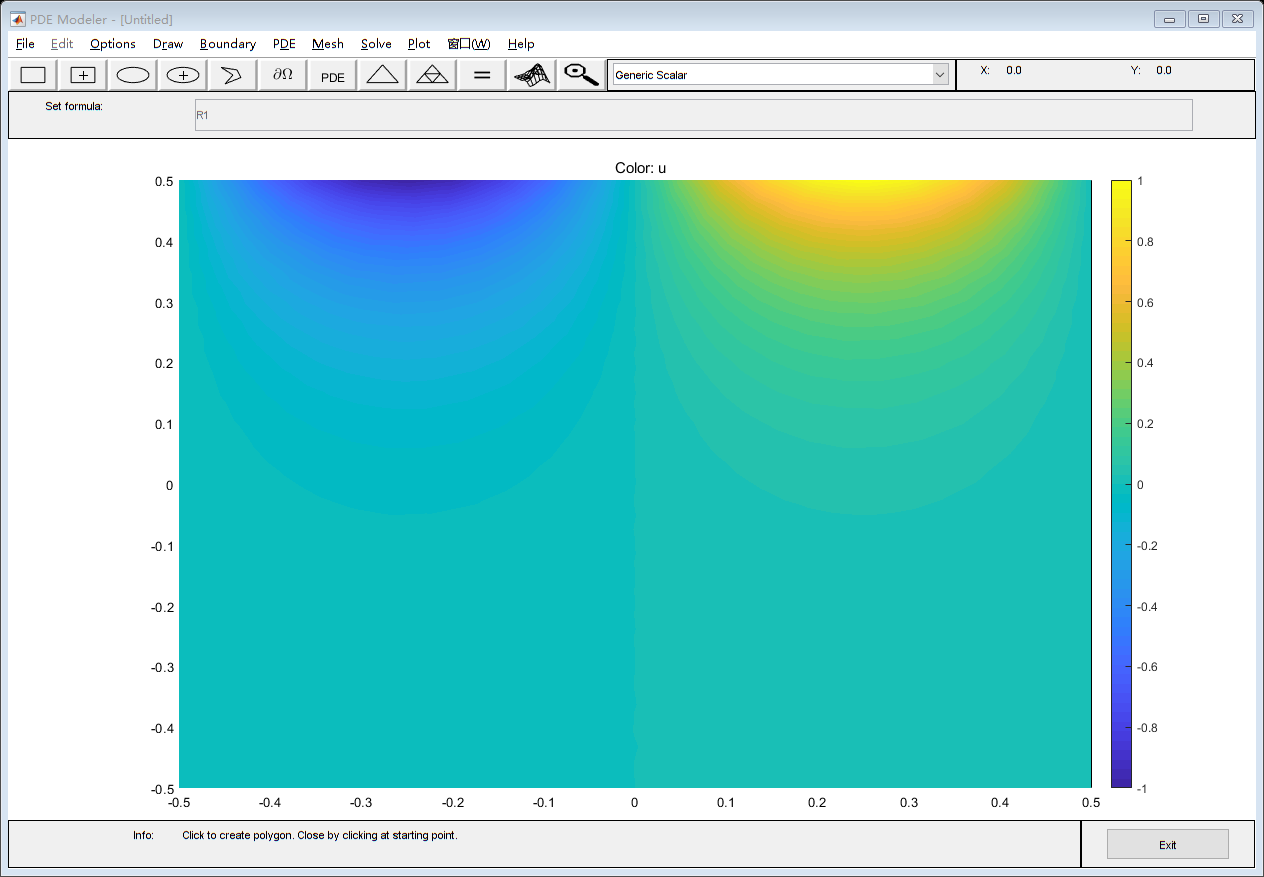

Static_Field('0','0','0','sin(2*pi*x)');

**    对比解析法和数值法得到的图形，可以看出二者几乎一致，从而证明了数值法的正确性。**

**        同理，可通过对边界条件的自定义设置，对难以解析求解的静态场进行计算：**

**x=0处的边界条件：**

x0 = 'sin(y)';

**x=1处的边界条件：**

x1 = 'cos(pi*y)';

**y=0处的边界条件：**

y0 = 'sin(2*pi*x)';

**y=1处的边界条件：**

y1 = 'cos(2*x)';

**        运行pdetool：**

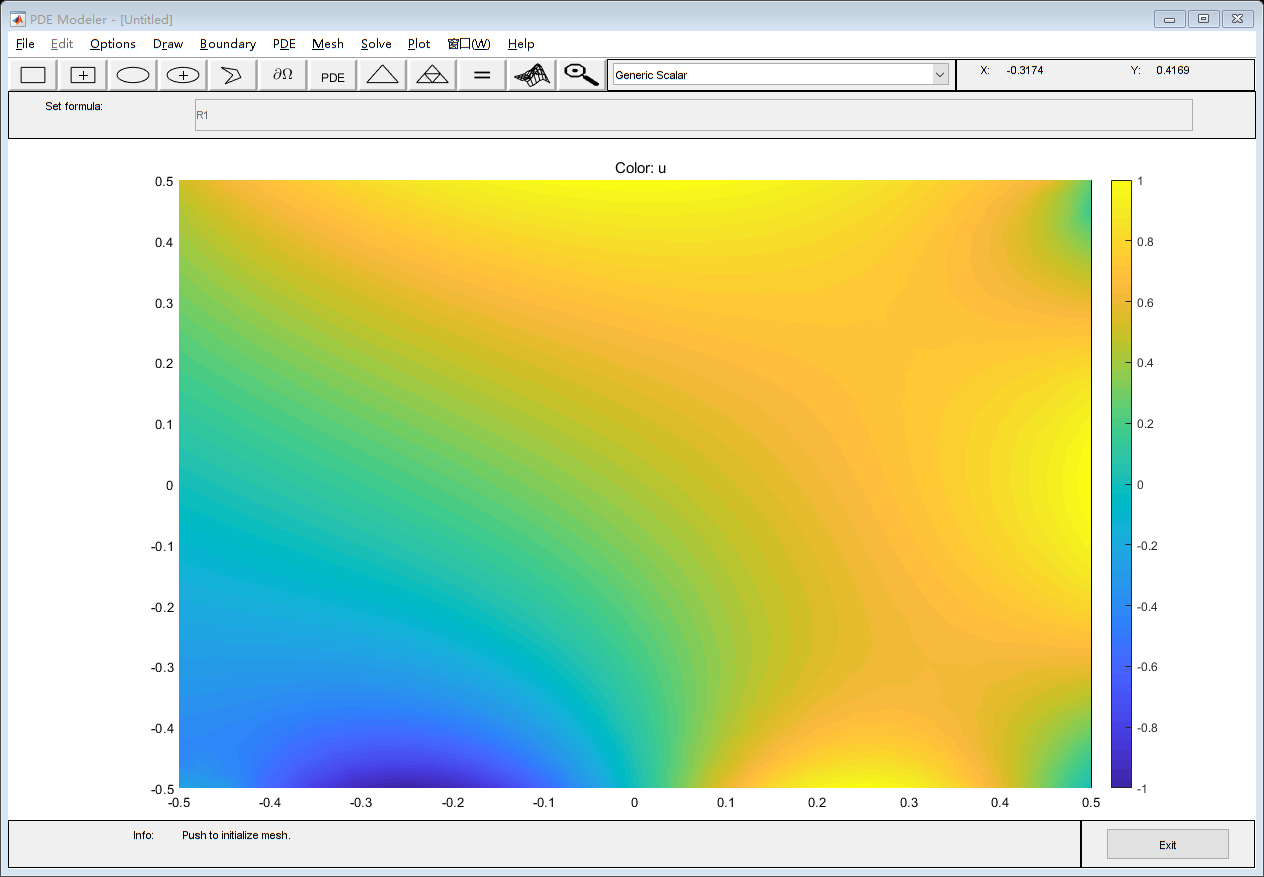

Static_Field(x0,x1,y0,y1);

function Static_Field(x0,x1,y0,y1)
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',1);
    set(ax,'DataAspectRatio',[1 1.5 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 3]);
    set(ax,'XLim',[-0.5 0.5]);
    set(ax,'YLim',[-0.5 0.5]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-0.5 0.5 0.5 -0.5],'R1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'dir',...
    1,...
    '1',...
    x0)
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    y0)
    pdesetbd(2,...
    'dir',...
    1,...
    '1',...
    x1)
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    y1)
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1.0',...
    '0.0',...
    '0',...
    '1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0';...
    '0.0';...
    '0  ';...
    '1.0'])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1872','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 10 1 0 0 0 1 1 0 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end